**Amir Azimi (4006123059)**

*Home Work 2*

clc; clear; close all;

1)

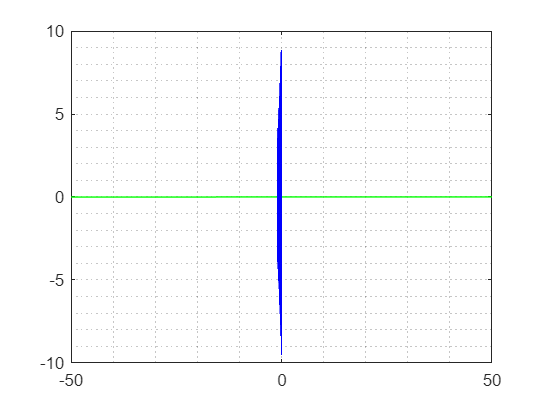

t = -50:100:50;
y = abs(sin(50*t) / t) * sin(t + pi);

figure(1);
plot(t, y, 'g');

hold on; grid minor;

z = linspace(-1+50i, 0.01+0.5i);
f = 10 * exp(z);
plot(z, f, 'b');


% close(1);

2)

n = 0:40;
y = 25 * cos(pi*n + 5).*exp(0.1*n);

figure(2);
stem(n, y)
close(2)

3)

a = 2;
b = 0.5;

theta = -100:0.1:100;
r = a*(1 - b^2)./(1 - b*cos(theta));

% r-theta
figure(3);
plot(theta, r);
close(3);

% drawing oval:
% theta = linspace(0, 2*pi, 100);
% r = a*(1 - b^2)./(1 - b*cos(theta))
% x = r.*cos(theta);
% y = r.*sin(theta);
% plot(x, y)

4)

x = -pi:0.1:pi;
y = -pi:0.1:pi;

[X, Y] = meshgrid(x, y);
f = cos(X).*cos(Y);

figure(4);
surf(X, Y, f);
close(4);

5) 

figure(5);

for i=1:30
    rand_x = randi(100);
    rand_y = randi(100);
    rand_r = randi(100);

    % draw_circle function is at the end of this file.
    draw_circle(rand_x, rand_y, rand_r)
    hold on;
end

close(5);

6)

syms x;

term = (x^2 - x - 1)*(x^3 - 2)*(x^2 - 3);

result = expand(term);
disp(result);

$$x^{7}-x^{6}-4\,x^{5}+x^{4}+5\,x^{3}+8\,x^{2}-6\,x-6$$

7)

syms i1 i2 i3 i4 i5;

eq1 = 470*i1 + 300*i2 - 5 == 0;
eq2 = -300*i2 + 560*i3 + 1000*i5 == 0;
eq3 = 100*i4 - 560*i3 + 10 == 0;
eq4 = -i1 + i2 + i3 + i4 == 0;
eq5 = -i3 - i4 + i5 == 0;

result = solve([eq1, eq2, eq3, eq4, eq5], [i1, i2, i3, i4, i5]);

disp(result);

    i1: 289/64438
    i2: 1553/161095
    i3: 463/32219
    i4: -6291/322190
    i5: -151/29290



8)

syms f(n) i;

f(n) = (1 / n)*log(1 + i/n);
sequence_result = symsum(f, i, 1, n);

result = limit(sequence_result, inf);
disp(sequence_result)

$$\frac{\log\left(\frac{\Gamma (2\,n+1)}{n^{n+1}}\right)-\log\left(\frac{\Gamma (n+1)}{n}\right)}{n}$$

disp(result)

$$2\,\log\left(2\right)-1$$

9)

syms y(x);

eq = diff(y, 2)-2*diff(y)+y == x*exp(x)+4;

Dy = diff(y);

result = dsolve(eq, [y(0)==1, Dy(0)==1]);

10) deleted question.

11)

n = -10:10;
dirac1 = dirac(n+4);
idx = (dirac1 == Inf); % find Inf
dirac1(idx) = 1; % set Inf to finite value
f1 = -5 * dirac1;

dirac2 = dirac(n);
idx = (dirac2 == Inf); % find Inf
dirac2(idx) = 1; % set Inf to finite value
f2 = dirac2;

dirac3 = dirac(n-3);
idx = (dirac3 == Inf); % find Inf
dirac3(idx) = 1; % set Inf to finite value
f3 = 2 * dirac3;

f = f1 + f2 + f3;

figure(6);
stem(n, f);
close(6);

**Functions**

function [] = draw_circle(x, y, r)
    theta = 0:.01:2*pi;
    x_data = r.*cos(theta) + x;
    y_data = r.*sin(theta) + y;
    plot(x_data, y_data)
end

*the end.*